# Solving the 1st Order Linear ODEs using Runge Kutta 2rd Order Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

In the realm of numerical analysis, solving complex differential equations accurately is often a daunting task. Enter the Runge-Kutta 2nd Order Method, a powerful numerical technique designed to provide more precise approximations to the solutions of ordinary differential equations. Building upon the foundation laid by the Euler method, this method offers improved accuracy by considering multiple intermediate steps within each interval. This introduction delves into the key concepts, underlying principles, and benefits of the Runge-Kutta 2nd Order Method, shedding light on how it strikes a balance between simplicity and accuracy to address the limitations of earlier approximation techniques.

Each 1st order ODE can be showed as a function of dependent variables. for example:


$$\frac{\mathrm{dy}}{\mathrm{dx}}=y^2 +3\sin \left(x\right)=f\left(x,y\right)$$


There are three common cases for this method, and they will be explained further in the subsequent sections of this document.

## Case1:

                        
$$y_{i+1} =y_i +\frac{1}{2}\;\left(k_1 +k_2 \right)\times h$$


                        
$$k_1 =f\left(x_i ,y_i \right)\;,\;k_2 =f\left(x_i +h,y_i +k_1 h\right)$$


### Part1: Input data

clear, clc
syms x
syms y
f = input('Enter the equation of f(x, y): ');
X = input('Enter the range of xi as a vector: ');
% Initialize the y values vector with the initial value y0
Y = zeros(1, length(X));
X(1, 1) = input('Enter the value of x0: ');
Y(1, 1) = input('Enter the value of y0: ');
h = input('Enter the value of step: ');          % Value of h (step size)
n = length(X);

### Part2: ODE Calculation

for i = 1:n-1
    k1 = subs(f, [x, y], [X(1, i), Y(1, i)]);
    k2 = subs(f, [x, y], [X(1, i) + h, Y(1, i) + k1 * h]);
    Y(1, i+1) = Y(1, i) + 0.5 * h * (k1 + k2);
    X(1, i+1) = X(1, i) + h;
end
Xi = X';
Yi = Y';
i = (0:n-1)';

### Part3: Results & Visualization

result = table(i, Xi, Yi);
disp('The results of calculation are:'), disp(result)

The results of calculation are:
    i     Xi       Yi  
    __    ___    ______

     0      0         1
     1    0.1      1.11
     2    0.2    1.2421
     3    0.3    1.3985
     4    0.4    1.5818
     5    0.5    1.7949
     6    0.6    2.0409
     7    0.7    2.3231
     8    0.8    2.6456
     9    0.9    3.0124
    10      1    3.4282
    11    1.1    3.8981
    12    1.2    4.4279
    13    1.3    5.0239
    14    1.4    5.6929
    15    1.5    6.4426
    16    1.6    7.2816
    17    1.7    8.2191
    18    1.8    9.2657
    19    1.9    10.433
    20      2    11.732



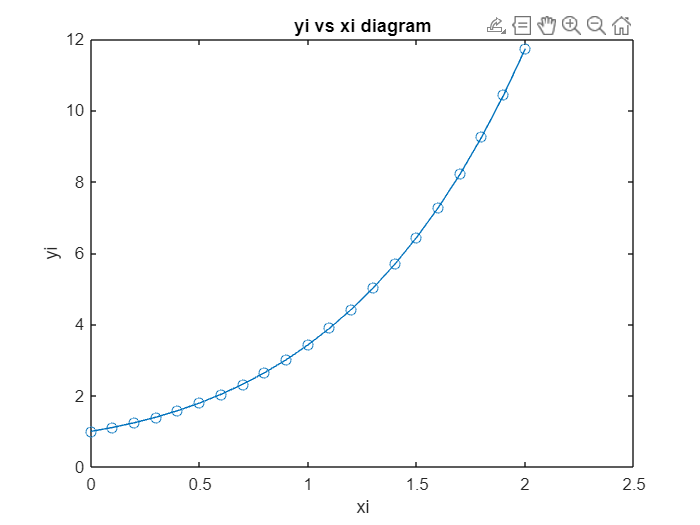

plot(X, Y, '-o')
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')

## Case2:

                        
$$y_{i+1} =y_i +k_2 h$$


                        
$$k_1 =f\left(x_i ,y_i \right)$$


                        
$$k_2 =f\left(x_i +\frac{h}{2},y_i +k_1 \frac{h}{2}\right)$$


### Part1: Input data

clear, clc
syms x
syms y
f = input('Enter the equation of f(x, y): ');
X = input('Enter the range of xi as a vector: ');
% Initialize the y values vector with the initial value y0
Y = zeros(1, length(X));
X(1, 1) = input('Enter the value of x0: ');
Y(1, 1) = input('Enter the value of y0: ');
h = input('Enter the value of step: ');          % Value of h (step size)
n = length(X);

### Part2: ODE Calculation

for i = 1:n-1
    k1 = subs(f, [x, y], [X(1, i), Y(1, i)]);
    k2 = subs(f, [x, y], [X(1, i) + (h/2), Y(1, i) + k1 * (h/2)]);
    Y(1, i+1) = Y(1, i) + k2*h;
    X(1, i+1) = X(1, i) + h;
end
Xi = X';
Yi = Y';
i = (0:n-1)';

### Part3: Results & Visualization

result = table(i, Xi, Yi);
disp('The results of calculation are:'), disp(result)
plot(X, Y, '-o')
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')

## Case3: (Ralston's Method)

                                
$$y_{i+1} =y_i +\left(\frac{k_1 }{3}+2\frac{k_2 }{3}\right)h$$


                                
$$k_1 =f\left(x_i ,y_i \right)$$


                                
$$k_2 =f\left(x_i +\frac{3}{4}h,y_i +\frac{3}{4}{h\times \;k}_1 \right)$$


### Part1: Input data

clear, clc
syms x
syms y
f = input('Enter the equation of f(x, y): ');
X = input('Enter the range of xi as a vector: ');
% Initialize the y values vector with the initial value y0
Y = zeros(1, length(X));
X(1, 1) = input('Enter the value of x0: ');
Y(1, 1) = input('Enter the value of y0: ');
h = input('Enter the value of step: ');          % Value of h (step size)
n = length(X);

### Part2: ODE Calculation

for i = 1:n-1
    k1 = subs(f, [x, y], [X(1, i), Y(1, i)]);
    k2 = subs(f, [x, y], [X(1, i) + (0.75*h), Y(1, i) + k1 * (0.75*h)]);
    Y(1, i+1) = Y(1, i) + (h/3)*(k1+2*k2);
    X(1, i+1) = X(1, i) + h;
end
Xi = X';
Yi = Y';
i = (0:n-1)';